filenameVRS = "C:\Users\silva.LSMEDIT\Documents\sciebo\ProjektSeminar\dataset\subject1\stage1\imgV2.mat";
load(filenameVRS);
perfCm = buildcmap('yrk');
barCm = buildcmap('bwr');

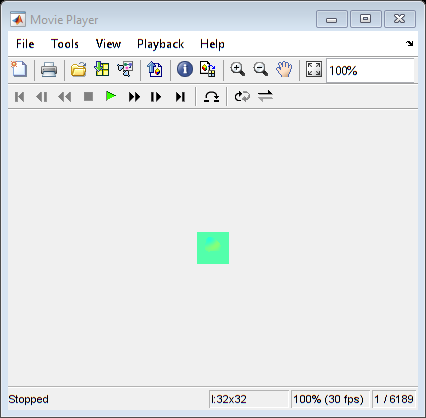

% Organize the data into "snapshots": spatial is rows, time is columns
stdMap = std(imgV2,[],3);
imgV2Filt = imgV2 .* repmat(stdMap > max(stdMap(:)) * 0.5, 1, 1, size(imgV2, 3));
flatV = reshape(imgV2Filt(:,:,1000:1500),32*32,[]);
X = flatV(:,1:end-2);
Y = flatV(:,2:end-1);

heartPix = [7,15];
lungPix = [14,22];

playVideo(imgV2Filt);

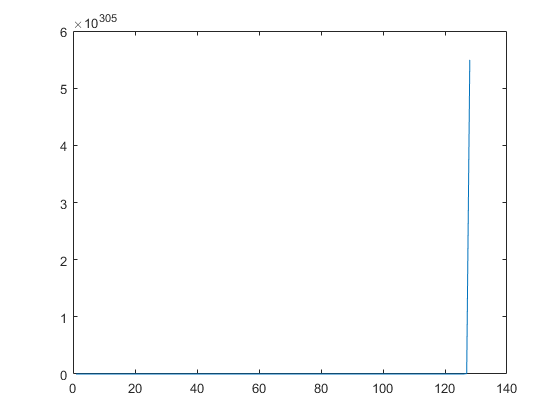

n = 0:(size(X,2) - 1);
x = 1:size(X,2);
Phi = hermiteH(n,sym(x));
figure; plot(Phi);